# **34754 Autonomous Robots Systems **

# Exercise 2: Kinematics and Odometry

## 2.1 Objective

The objective of this exercise is to give an introdution to kinematics and odometry for mobile robots.

## 2.2 Material and preparation

The material for this exercise is found in "Where am I", section 1 and 5 and UMB-mark chapter 6.

## 3.3 Calculation of vehichle position

The aim is to calculate and cntrol where we are and where we are going. Kinematics is the study of motion without regard to the force which cause it. Within kinematics one studies the position and accecleration etc. First we calculate where we are based on encoder measurements. This is called the odometry model. 

The **incremntal displacement **of each **wheel**


$$\Delta U_{L/R}(i)=c_mN_{L/R}(i)$$


where $c_m=\frac{\pi D}{nC}$, where $D$ is the diameter of the wheels, $n$ is the gear ratio between the encoder and wheel and $C$ is the number of pulses per revolution. 

**Center point displacement **is given by 

$\Delta U(i)=\frac{\Delta U_r +\Delta U_L}{2}$.

The **incremntal change in orientation **is given by


$$\Delta \theta(i)=\frac{\Delta U_R-\Delta U_L}{b}$$


Where $b$ is the wheel distance (distance between the two wheels).

The new pose of the robot is therefore


$$x(i)=x(i-1)+\Delta U(i) \cdot \cos(\theta(i))$$



$$y(i)=y(i-1)+\Delta U(i) \cdot \sin(\theta(i))$$



$$\theta (i) = \theta(i-1)+\Delta \theta (i)$$


D=0.065; % Diameter of the wheels
N=1;     % Gear ration between encoder and wheel
C=2000;  % Number of pulses per revolution
b=0.26;  % Distance between wheels given in meters
L=1;     % Side lengt

### 3.3.1 Matlab script to calculate $E_b$ and $E_d$

Make a matlab script that takes the errors from a clockwise experiment $X_{cw}$ and $Y_{cw}$ and the errors from a counter clockwise experiment $X_{ccw}$ and $Y_{ccw}$ and the side length $L$ and the nominal width as inputs and calculate $E_d$ and $E_b$ as output.

The formula for $\beta$ is


$$\beta=\frac{x_{c., g.,cw}-x_{c., g.,ccw}}{-4L}\cdot \frac{180}{\pi}
$$


and for the y-coordinate


$$\beta=\frac{y_{c., g.,cw}+y_{c., g.,ccw}}{-4L}\cdot \frac{180}{\pi}
$$


The radius of the curvature $R$ of the curved path can be found using simple geometric relations. The radius is given as:


$$R=\frac{L/2}{\sin(\beta/2)}$$


We can at last determine the ration between the two wheel diameters that caused the robot to travel on a curved, instead of a straight path (see fig. 6.4):


$$E_d=\frac{D_R}{D_L}=\frac{R+b/2}{R-b/2}$$


% First get the beta values
[beta_x, beta_y] = calcBeta(0.2,0.12, 0.2, -0.12, L)

beta_x = -0.0200

beta_y = -0.0200


% Let's mean the values to make one beta value
beta=(beta_x+beta_y)/2

beta = -0.0200


% Calculate the radius
R = calcR(L, beta)

R = -50.0008

R = -50.0008


% At last we can calucate Ed
Ed = (R+b/2)/(R-b/2)

Ed = 0.9948

Let's calculate the wheelbase error $E_b$. For this we need to calculate $\alpha$ which is given by 


$$\alpha=\frac{x_{c., g.,cw}+x_{c., g.,ccw}}{-4L}\cdot \frac{180}{\pi}
$$


and for the y-coordinate


$$\alpha=\frac{y_{c., g.,cw}-y_{c., g.,ccw}}{-4L}\cdot \frac{180}{\pi}
$$


We then have the equation


$$E_b=\frac{90^\circ}{90^\circ - \alpha}$$


% First get the beta values
[alpha_x, alpha_y] = calcAlpha(0.2,0.12, 0.2, -0.12, L)

alpha_x = -0.0800

alpha_y = -0.0800


% Let's mean the values to make one beta value
alpha=(alpha_x+alpha_y)/2

alpha = -0.0800

Eb = (90/(90-alpha*(180/pi)))

Eb = 0.9515

### 3.3.2 UMB-mark in the simulator

Now let's try with som values from the simulator. 

% Observed values
L=2;
x_cw = 0.266;
y_cw = 2-2.217;
x_ccw = 0.266;
y_ccw = 2-1.783;

Find $E_d$:

[beta_x, beta_y] = calcBeta(x_cw, x_ccw, y_cw, y_ccw, L);
beta=(beta_x+beta_y)/2;
R = calcR(L, beta);

R = 8.9885e+307

Ed = (R+b/2)/(R-b/2)

Ed = 1

And let's find $E_b$:

% First get the beta values
[alpha_x, alpha_y] = calcAlpha(x_cw, x_ccw, y_cw, y_ccw, L)

alpha_x = -0.0665

alpha_y = 0.0543


% Let's mean the values to make one beta value
alpha=(alpha_x+alpha_y)/2

alpha = -0.0061

Eb = (90/(90-alpha*(180/pi)))

Eb = 0.9961

The new wheel base value $b$

b_new = (90/(90-alpha*(180/pi)))*b

b_new = 0.2590

# Exercise 4: Robot programming in C

## 4.2 Robot hardware interface RHD

We modified the square program so that the SMR turns around the center of the vehicle instead of one wheel. This was done by changing:

## 4.3 Basic Motion Control and Odometry

We will in the following change the square.c script through several tasks.

### 4.3.1 Logging the square program

Two function were made for logging:

The sm_saveArray() function is called through the update_motcon() function, and the writeToFile() function is called at last (just before exit). 

**Answers to questions:**

*Why should we use a statically allocated array? *

A static array is used because we can find the size of the array, because of that we do not need to be responsible for allocating the memory, and the program is faster. 

*Think about what happens if the end of the array is reached. *

If the end of the arrays is reached and more data is added to the array, it gives undefined behaviour.

*Run the square program with logging and make a matlab plot of the motorspeeds versus time.*

lrspeed=importdata('log.dat');
figure(1);
subplot(1,2,1)
plot(lrspeed(1:end, 2))
title("Left")
xlabel("Time")
ylabel("Speed [m/s]")
ylim([-0.2, 0.35])


subplot(1,2,2)
plot(lrspeed(1:end, 3))
title("Right")
xlabel("Time")
ylabel("Speed [m/s]")
ylim([-0.2, 0.35])

### 4.3.2 Implement odometry

We have to find x, y and theta in the square program.

First, we added some new variables to the odotype struct:

Next we changed the update_odo function, caluclating the different odometry using the formulas from the "Where am I" book, page 20:

and at last we wish to update the reset_odo function to reset our new variables by adding the line:

We updated the logging function from before, containing the new variables, and ran the clockwise and counter-clockwise square. We wish to sanity check our results by ploting the individual positions over time:

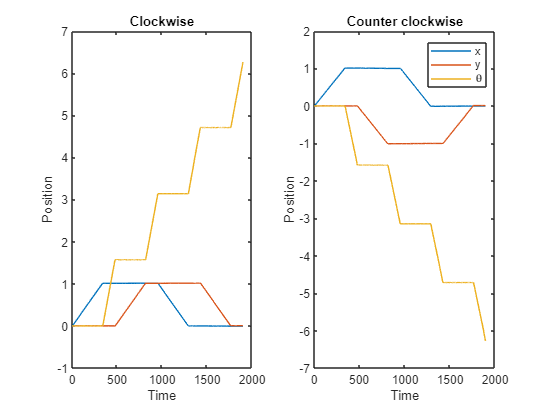

odo_cw=importdata('ex_4_3_2_cw.dat');
figure(2);
subplot(1,2,1)
plot(odo_cw(1:end,4:6))
title("Clockwise")
xlabel("Time")
ylabel("Position")

odo_ccw=importdata('ex_4_3_2_ccw.dat');
subplot(1,2,2)
plot(odo_ccw(1:end,4:6))
legend(["x", "y", "\theta"])
title("Counter clockwise")
xlabel("Time")
ylabel("Position")

Below we plot the xy-plot for both clockwise and counter clockwise:

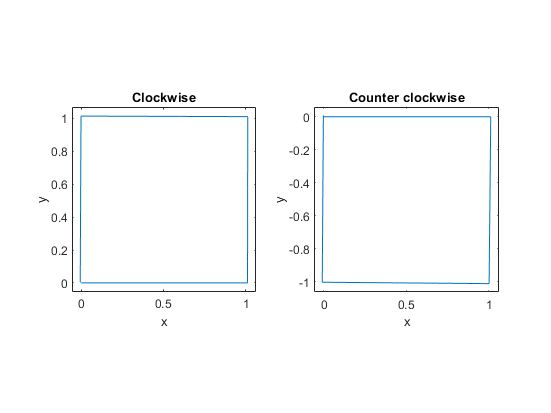

spacing = 0.05;

odo_cw=importdata('ex_4_3_2_cw.dat');
figure(3);
subplot(1,2,1)
plot(odo_cw(1:end,4), odo_cw(1:end,5))
title("Clockwise")
xlabel("x")
ylabel("y")
axis equal;
xlim([min(odo_cw(1:end,4))-spacing, max(odo_cw(1:end,4))+spacing])
ylim([min(odo_cw(1:end,5))-spacing, max(odo_cw(1:end,5))+spacing])

odo_ccw=importdata('ex_4_3_2_ccw.dat');
subplot(1,2,2)
plot(odo_ccw(1:end,4), odo_ccw(1:end,5))
title("Counter clockwise")
xlabel("x")
ylabel("y")
axis equal;
xlim([min(odo_ccw(1:end,4))-spacing, max(odo_ccw(1:end,4))+spacing])
ylim([min(odo_ccw(1:end,5))-spacing, max(odo_ccw(1:end,5))+spacing])

### 4.3.3 Modify the square program and plot x, y and $\theta$

To make the SMR move 2m and stop at different speeds, we changed the case of moving foward so it just ends after moving forward, and moves 2 meters with different velocities. We then changed the speed by simply commenting out the different lines:

Below we plotted the x, y and $\theta$ value over time:

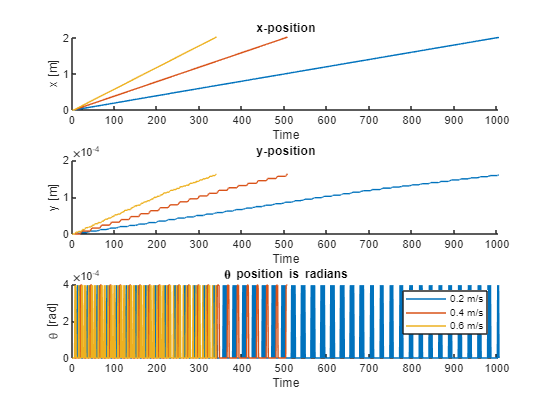

odo02=importdata('ex_4_3_3_02.dat');
odo04=importdata('ex_4_3_3_04.dat');
odo06=importdata('ex_4_3_3_06.dat');

exe4_plot(odo02, odo04, odo06)

### 4.3.4 Limit the acceleration

As above, we wish in the end to plot the x, y and $\theta$. However, this time we limit the acceleration to $0.5\frac{m}{s^2}$. This is done by inserting the following statements in the update_motcon function insted of the old motorspeed configuaration:

where the tick accelleration is defined as the frequency over the acceleration:

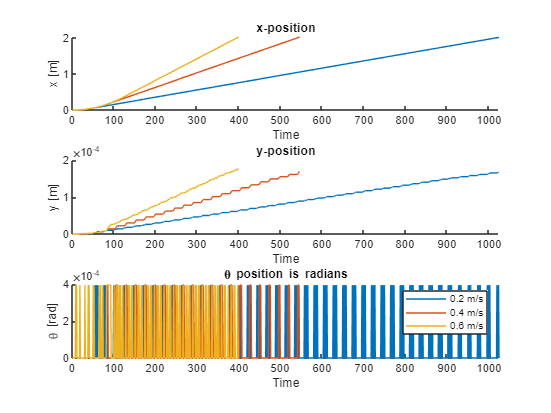

odo02=importdata('ex_4_3_4_02.dat');
odo04=importdata('ex_4_3_4_04.dat');
odo06=importdata('ex_4_3_4_06.dat');

exe4_plot(odo02, odo04, odo06)

### 4.3.5 Deceleration

As before,we wish to plot the x, y and $\theta$ value for going 2 meters, however this time we limit the decelleration of the SMR using the formula $V_{max}=\sqrt{2a_{max}d}$. This was done by measuring the distance, and using the formula given in the update_motcon function:

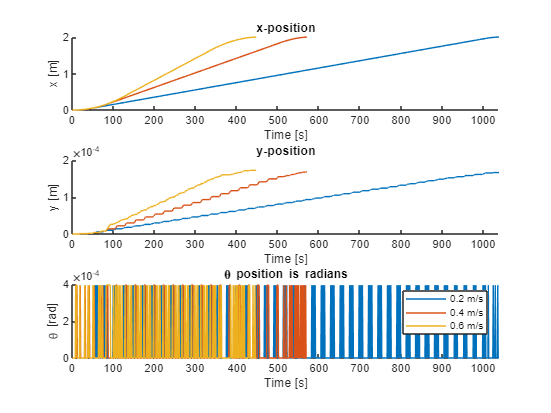

odo02=importdata('ex_4_3_5_02.dat');
odo04=importdata('ex_4_3_5_04.dat');
odo06=importdata('ex_4_3_5_06.dat');

exe4_plot(odo02, odo04, odo06)

### 4.3.6 Adding acceleration and deceleration to the turn

We made a series of code changes to the mot_turn function:

Which resulted in the following x, y and $\theta$ values when doing the clockwise and counter clockwise square:

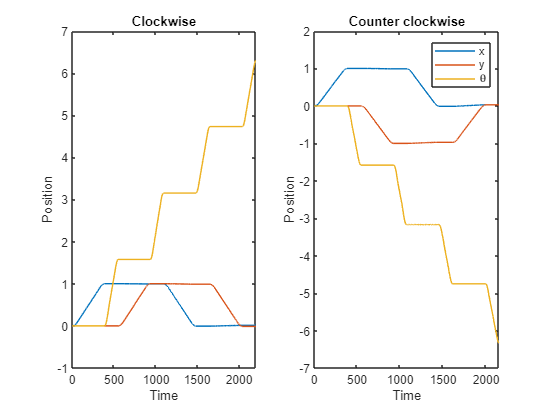

odo_cw=importdata('ex_4_3_6_cw.dat');
figure(4);
subplot(1,2,1)
plot(odo_cw(1:end,4:6))
title("Clockwise")
xlabel("Time")
ylabel("Position")

odo_ccw=importdata('ex_4_3_6_ccw.dat');
subplot(1,2,2)
plot(odo_ccw(1:end,4:6))
legend(["x", "y", "\theta"])
title("Counter clockwise")
xlabel("Time")
ylabel("Position")

We find that the corners of the curves has been rounded, which make a lot of sense as the SMR acceleration and deceleration has been applied both before,under and after the turns.

# 5. Laserscanner

## 5.3 Running the simulator with the Square Program

# Appendix A: Functions 

function [beta_x, beta_y] = calcBeta(x_cw,x_ccw, y_cw, y_ccw, L)
    beta_x = ((x_cw-x_ccw)/(-4*L));
    beta_y = ((y_cw+y_ccw)/(-4*L));
end

function [alpha_x, alpha_y] = calcAlpha(x_cw,x_ccw, y_cw, y_ccw, L)
    alpha_x = ((x_cw+x_ccw)/(-4*L));
    alpha_y = ((y_cw-y_ccw)/(-4*L));
end

function [R] = calcR(L, beta)
    R=(L/2)/sin((beta+realmin)/2)
end

### Plot function for exercise 4

function [] = exe4_plot(log1, log2, log3)    
    max_time = (max([length(log1), length(log2), length(log3)]));
    clf();
    
    figure;
    subplot(3,1,1)
    hold on
    plot(log1(1:end,4))
    plot(log2(1:end,4))
    plot(log3(1:end,4))
    hold off
    title("x-position")
    xlabel("Time [s]")
    ylabel("x [m]")
    xlim([0, max_time])
    
    subplot(3,1,2)
    hold on
    plot(log1(1:end,5))
    plot(log2(1:end,5))
    plot(log3(1:end,5))
    hold off
    title("y-position")
    xlabel("Time [s]")
    ylabel("y [m]")
    xlim([0, max_time])
    
    subplot(3,1,3)
    hold on
    plot(log1(1:end,6))
    plot(log2(1:end,6))
    plot(log3(1:end,6))
    hold off
    title("\theta position is radians")
    xlabel("Time [s]")
    ylabel("\theta [rad]")
    legend(["0.2 m/s", "0.4 m/s", "0.6 m/s"])
    xlim([0, max_time])
end